# Matriz Y Barra

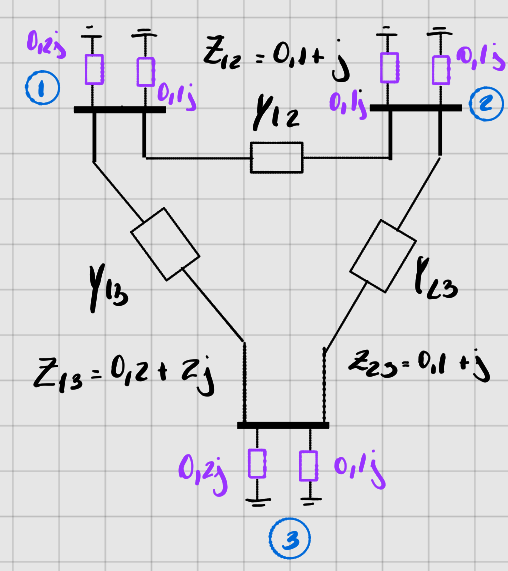

%             Env Rec Rs[pu]  Xs[pu]  Ysh[pu] Rel_transf_tensao(a)[pu]    Ang_def (rad)
Dados_linha=[ 1    2    0.1   1.000    0.10          1                      0;
              1    3    0.2   2.000    0.20          1                      0;
              2    3    0.1   1.000    0.10          1                      0;];

## 1. Extraindo os dados da linha de transmissão 

Orig =  Dados_linha(:, 1);
Dest =  Dados_linha(:, 2);
Rs   =  Dados_linha(:, 3);
Xs   =  Dados_linha(:, 4);
bsh  =  Dados_linha(:, 5);
a    =  Dados_linha(:, 6);
phi  =  Dados_linha(:, 7);
NumLT =    size(Orig, 1);

## 2. Montagem da matriz Y Barra

Y = zeros(NumLT, NumLT);
Ysh = zeros(NumLT, NumLT);

### 2.1 Elementos fora da diagonal principal

Correspondem ao negativo da admitancia entre barras, ou a soma das admitâncias que ligam as barras k e j

% Admitâncias
for k = 1:NumLT
    Ykj = -1/(Rs(k) + 1i * Xs(k));
    Y(Orig(k), Dest(k)) = Ykj; % Diagonal superior
    Y(Dest(k), Orig(k)) = Ykj; % Diagonal inferior
end

% Admitância shunt
for k = 1:NumLT
    Ysh(Orig(k), Dest(k)) = 1i * bsh(k); % Diagonal superior
    Ysh(Dest(k), Orig(k)) = 1i * bsh(k); % Diagonal inferior
end

### 2.3 Elementos da diagonal principal

Corresponde ao somatório de todas as admitâncias conectadas a barra

YBarra = Y;
for k = 1: NumLT
    YBarra(k, k) = -sum(Y(k, :)) -sum(Ysh(k, :));
end

G_barra = real(YBarra)

G_barra =     0.1485   -0.0990   -0.0495
   -0.0990    0.1980   -0.0990
   -0.0495   -0.0990    0.1485


B_barra = imag(YBarra)

B_barra =    -1.7851    0.9901    0.4950
    0.9901   -2.1802    0.9901
    0.4950    0.9901   -1.7851
